% make sure we have a clean environment
clear
rand('state',0);
randn('state',0);

% Global variables
% H     - the recorded head for each time
% TM    - the times the head was recorded
% SIGMA - the standard deviation for a time
% D     - the distance between the wells
% Q     - the volume of the slug
global H;
global TM;
global SIGMA;
global Q;
global D;
global stepsize

%
% Load the data.  Head is measured to the nearest centimeter.  
%
load slugdata.mat
%
%
% Fixed parameter values.
%
D=60;
Q=50;

% We'll use sigma=1cm.  
SIGMA=0.01*ones(size(H));

S_sig = 2e-5;
T_sig = 4e-2;
stepsize = [S_sig; T_sig];
S0 = 5e-3; T0 = 1;
m0 = [S0;T0]; 
N = 2e5; BURNIN = 1e4;
skip = 1000;

### 4.(a) Identify the number of samples that remain after the thinning process. Plot the hisstory of the thinned posterior samples, and include the true parameters.

logprior = @(m) Logprior(m);
loglikelihood = @(m) Loglikelihood(m);
generate = @(x,stepsize) Generate(x);
logproposal = @(x,y,stepsize) Logproposal(x,y);

[mout,mMAP,pacc]=mcmc(logprior,loglikelihood,generate,logproposal,m0,N)

mout =     0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049
    1.0000    0.9334    0.9334    0.9334    0.9334    0.9334    0.9334    0.9334    0.9379    0.9379    0.9046    0.8512    0.8512    0.8512    0.7874    0.8103    0.8103    0.8103    0.8103    0.7622    0.7559    0.7662    0.7662    0.7662    0.7293    0.7270    0.7515    0.7515    0.7258    0.6854    0.6835    0.6708    0.6708    0.6708    0.6708    0.6708    0.6708    0.6590    0.6496    0.6622    0.6622    0.6622    0.6622    0.6622    0.6325    0.6325    0.6325    0.6325    0.6325  

mMAP =     0.0021
    0.5854


pacc = 0.2938

%downsample results to reduce correlation
k=(BURNIN:skip:N);
mskip=mout(:,k);
disp(['The corresponding number of samples = ',num2str(length(mskip)),' samples']);

The corresponding number of samples = 191 samples


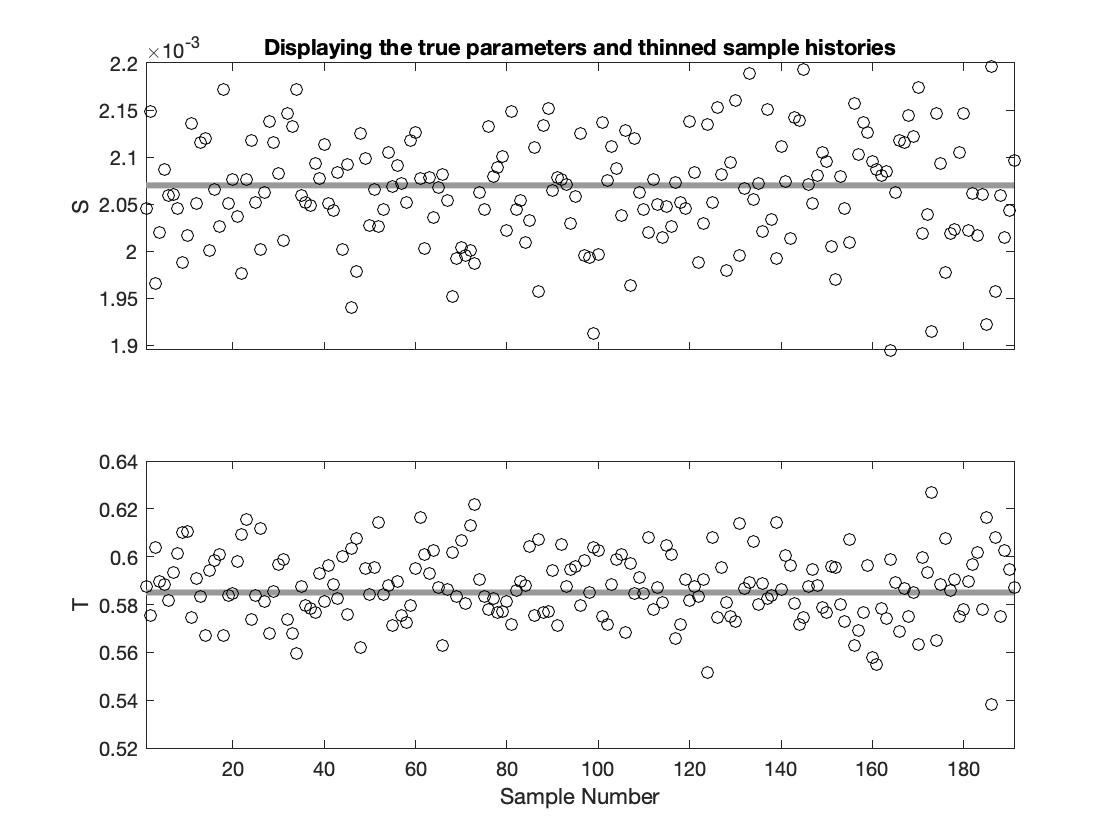


mtrue = [0.00207;0.585];

%plot parameter sample histories
figure(1)
clf
for i=1:2
  subplot(2,1,i)
  plot([1 length(mskip)],[mtrue(i) mtrue(i)],'Color',[0.6 0.6 0.6],'LineWidth',3);
  hold on
  plot(mskip(i,:),'ko')
  hold off
  if i~=2
    set(gca,'Xticklabel',[]);
  end
  xlim([1 length(mskip)])
end
xlabel('Sample Number')
subplot(2,1,1)
ylabel('S')
title('Displaying the true parameters and thinned sample histories')
subplot(2,1,2)
ylabel('T')

There is anti-correlation in the sequence of parameter samples S and T.

### b) Plot autocorrelations of S and T both before and after thinning. Discuss if there was enough thinning with skipping every 1000 samples.

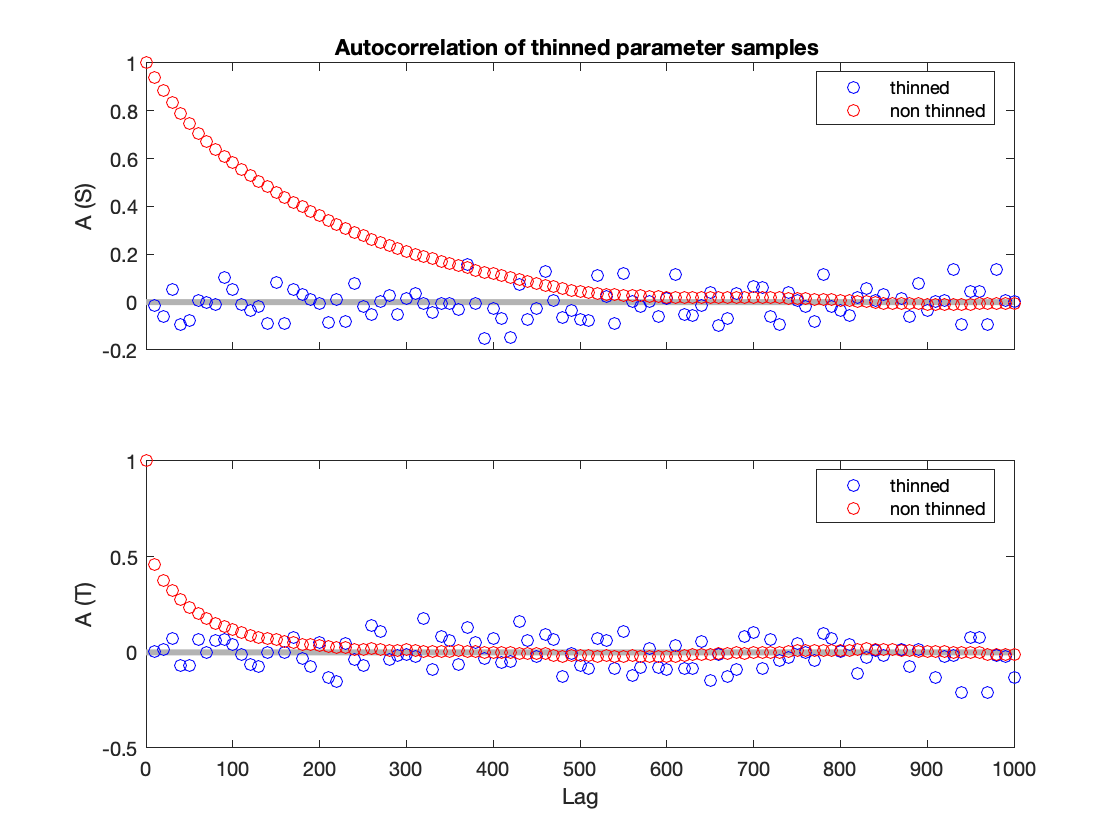

figure(2)
clf
laglen=1000;
lags=(-laglen:laglen)';
acorr=zeros(2*laglen+1,2);
acorrn=zeros(2*laglen+1,2);

for i=1:2
      acorrn(:,i)=calc_corr(mout(i,:)',laglen);
end

for i=1:2
  acorr(:,i)=calc_corr(mskip(i,:)',laglen);
  subplot(2,1,i);
  plot([0 laglen],[0 0],'Color',[0.7 0.7 0.7],'LineWidth',3); hold on
  plot(lags(laglen+1:10:laglen*2+1),acorr(laglen+1:10:laglen*2+1,i),'bo');
  plot(lags(laglen+1:10:laglen*2+1),acorrn(laglen+1:10:laglen*2+1,i),'ro');
  legend('','thinned', 'non thinned',Location='best')
  hold off
  if i == 1
     ylabel(['A (S)'])
     title('Autocorrelation of thinned parameter samples ')
  else
      ylabel(['A (T)'])
  end
  
  if i~=2
    set(gca,'Xticklabel',[]);
  end
end
xlabel('Lag')

 According to the graph above, we observe before thining, the 1000 samples are positively auto correlated, and after thinning with skipping every 1000 steps,  the thinned samples (blue) are effectively decorrelated, hence there was no enough thining with skipping every 1000 samples.

### (c) Estimate the 95% credible intervals by sorting the ensemble of parameter estimates, as is done in Exercise 11.4.

% estimate the 95% credible intervals
for i=1:2
  msort=sort(mskip(i,:));
  m2_5(i) = msort(round(2.5/100*length(mskip)));
  m97_5(i) =  msort(round(97.5/100*length(mskip)));
  disp(['95% confidence interval for m', num2str(i),' is [', num2str(m2_5(i)),',', num2str(m97_5(i)),']'])
end

95% confidence interval for m1 is [0.00194,0.0021714]
95% confidence interval for m2 is [0.55971,0.61428]


### (d) Estimate the Bayesian confidence intervals as we've done previously, using the standard deviation of the MCMC samples.

for i=1:2
  msort=sort(mskip(i,:)); Mmap = 1.96*std(msort);
  m97_5b = mMAP(i) + Mmap;
  m2_5b =  mMAP(i) - Mmap;
  disp(['95% confidence interval for m', num2str(i),' is [', num2str(m2_5b),',', num2str(m97_5b),']'])
end

95% confidence interval for m1 is [0.0019561,0.0021834]
95% confidence interval for m2 is [0.55712,0.61364]


### (e) As in Figure 11.16, plot the sampled posterior distribution S vs T with the true model as a large black dot, and the MAP estimate with an open circle. On the same graph plot the thinned samples as gray dots and 95% credible intervals by a box.

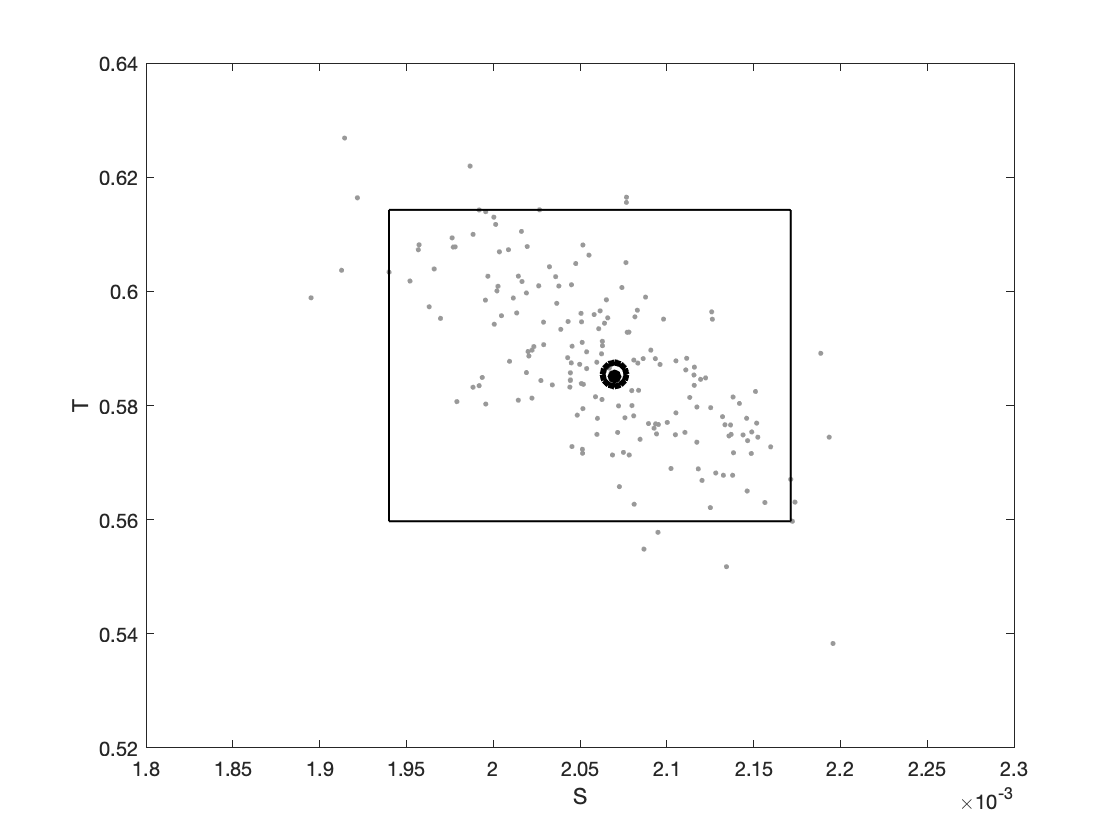

%plot a scatter plot and histogram of the posterior distribution
mlims=[0.0018 0.0023; 0.52 0.64];

figure(3)
clf
for i=1:2
  for j=1:2
    if i==j
        continue
    else
      plot(mskip(j,:),mskip(i,:),'k.','Markersize',6,'Color',[0.6 0.6 0.6]);
      hold on
      % plot the true answer as a large black dot
      plot(mtrue(j),mtrue(i),'k.','Markersize',24);
      % plot the accepted answers as gray dots
      plot(mMAP(j),mMAP(i),'ko','Markersize',12,'LineWidth',3);
      % plot the 95% ci as a box
      plot([m2_5(j),m97_5(j)],[m2_5(i),m2_5(i)],'k-','LineWidth',1);
      plot([m2_5(j),m97_5(j)],[m97_5(i),m97_5(i)],'k-','LineWidth',1);
      plot([m2_5(j),m2_5(j)],[m2_5(i),m97_5(i)],'k-','LineWidth',1);
      plot([m97_5(j),m97_5(j)],[m2_5(i),m97_5(i)],'k-','LineWidth',1);
      xlim(mlims(j,:));
      ylim(mlims(i,:));
      
      xlabel('S'); ylabel('T')
      
      hold off
    end
  end
end

From the graph above almost all the thinned samples are captured inside the box, and the MAP estimates and the true model parameters are enclosed, almost to the cennter of the box

### (f) Apply a Q-Q plot and discuss the normality of the sampled posterior distribution. In your discussion, address how the 95% credible intervals play a role.

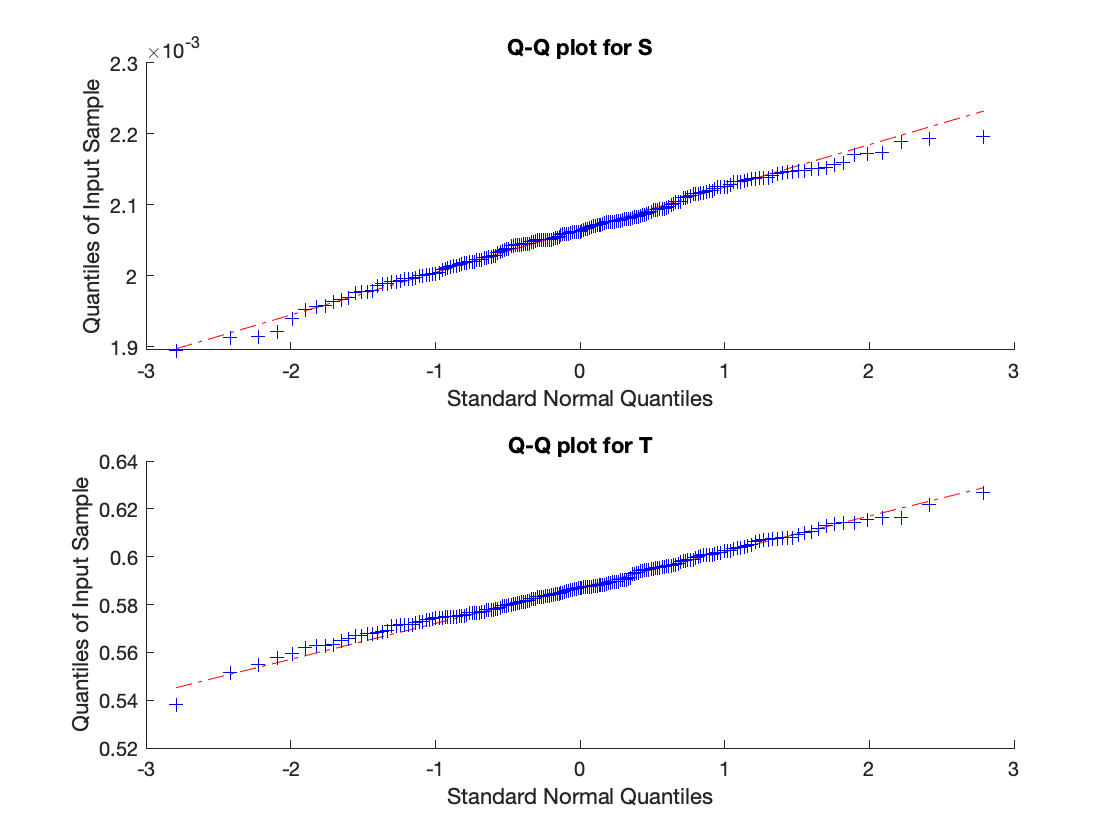

figure(4)
for i = 1:2
    subplot(2,1,i)
    qqplot(sort(mskip(i,:)))
    ylabel('Quantiles of Input Sample');
    xlabel('Standard Normal Quantiles');
    if i == 1
        title('Q-Q plot for S')
    else
        title('Q-Q plot for T')
    end
end

Since  the graphical test from the Q-Q plot depicts that the quantile data and standard normal quantiles almost follow a straight line between -1.8 to 1.8 for both parameters then the MCMC data samples with a 95% credible interval exhibit a normal distribution.

function l = Loglikelihood(m)
    global H;
    global TM;
    global SIGMA;
    global D;
    global Q;
    
    % Compute the standardized residuals.
    fvec = fun(m);

    % The log likelihood is (-1/2)*sum(fvec(i)^2,i=1..n);
    l = (-1/2)*sum(fvec.^2);
end

function lp = Logprior(m)
    if (m(1)>=0) && (m(1)<=0.01) && (m(2)>=0) && (m(2)<=2)
      lp=0;
    else
      lp=-Inf;
    end
end

function y=Generate(x)
    global stepsize
    y=x+stepsize.*randn(2,1);
end

function lr=Logproposal(x,y)
    global stepsize
    
    lr=(-1/2)*sum((x-y).^2./stepsize.^2);
end